Forecast monthly runoff with ARIMA

## 1 Clear workspace

clear
close all
clc

## 2 Read monthly runoff

data_path='../time_series/';
station='Zhangjiashan' %'Huaxian', 'Xianyang' or 'Zhangjiashan'

station = 'Zhangjiashan'

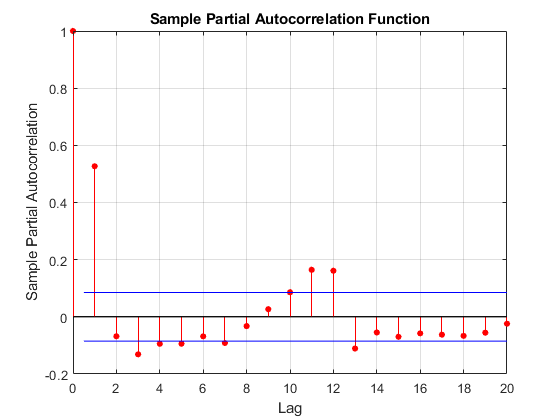

switch station
    case 'Huaxian'
        save_path = '../Huaxian/projects/arma/';
        data = xlsread([data_path,'HuaxianRunoff1951-2018(1953-2018).xlsx'],1,'B26:B817');%full=792samples
    
    case 'Xianyang'
        save_path = '../Xianyang/projects/arma/';
        data = xlsread([data_path,'XianyangRunoff1951-2018(1953-2018).xlsx'],1,'B26:B817');%full=792samples
        
    case 'Zhangjiashan'
        save_path = '../Zhangjiashan/projects/arma/';
        data = xlsread([data_path,'ZhangJiaShanRunoff1953-2018(1953-2018).xlsx'],1,'B2:B793');%full=792samples
end

if exist(save_path,'dir')==0
   mkdir(save_path);
end

train_len = 552;
dev_len=120;
test_len=120;

train = data(1:train_len);
dev = data(train_len+1:train_len+dev_len);
test = data(train_len+dev_len+1:length(data));

parcorr(train)

autocorr(train)

## 3 Tune ARIMA models

tic
mse = zeros(20,20);
parfor p =1:20
    for q=1:20
        m = armax(train,[p,q]);
        dev_pred = predict(m,dev,1);
        mse(p,q)= (sum((dev-dev_pred).^2)/length(dev));
    end
end
elapsedTime = toc

elapsedTime = 45.7166

## 4 Predict the train, dev and test set

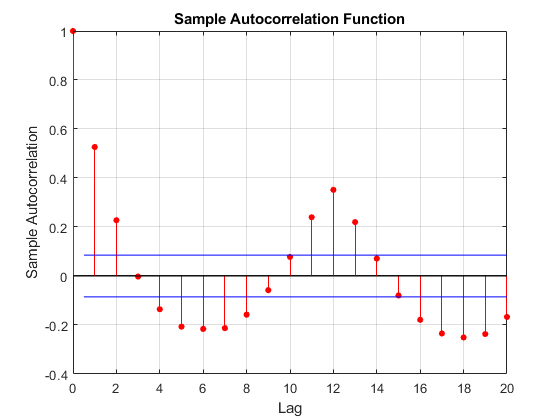

minimum = min(min(mse));
[p_,q_]=find(mse==minimum);
m = armax(train,[p_,q_]);

train_pred = predict(m,train,1);
dev_pred = predict(m,dev,1);
test_pred = predict(m,test);

train_pred(train_pred<0)=0;
dev_pred(dev_pred<0)=0;
test_pred(test_pred<0)=0;

nse_train = NSE(train,train_pred);
nse_dev = NSE(dev,dev_pred);
nse_test = NSE(test,test_pred);

nrmse_train =NRMSE(train,train_pred);
nrmse_dev = NRMSE(dev,dev_pred);
nrmse_test = NRMSE(test,test_pred);

ppts_train = PPTS(train,train_pred,5);

y_true_ =     8.8145
    8.0857
    8.0733
    8.0319
    7.8636
    7.7281
    7.6933
    7.1028
    7.0723
    6.6680


y_true_order =    165
   428
   163
   212
   248
   140
    68
   476
   141
    67


y_pred_ =     4.3439
    3.7213
    2.9099
    2.6003
    3.6070
    4.1617
    5.1786
    2.0237
    5.2012
    3.3730


ppts_dev = PPTS(dev,dev_pred,5);

y_true_ =     5.3903
    4.9616
    3.4595
    3.4291
    2.3507
    2.0097
    1.9904
    1.8484
    1.7681
    1.6565


y_true_order =     58
    56
    57
     7
    68
    79
    33
    82
    44
    42


y_pred_ =     2.5703
    1.5334
    2.3043
    2.6456
    1.8027
    1.4878
    1.1890
    0.9445
    1.8280
    0.9389


ppts_test = PPTS(test,test_pred,5);

y_true_ =     4.9550
    4.9217
    4.5368
    3.5694
    3.2409
    2.2503
    1.9596
    1.8530
    1.8057
    1.7675


y_true_order =    115
    55
    20
    33
   116
    21
   117
    19
    56
     8


y_pred_ =     1.3600
    1.8850
    2.8899
    1.7632
    2.8056
    2.2338
    2.0537
    0.0452
    2.5944
    1.6179


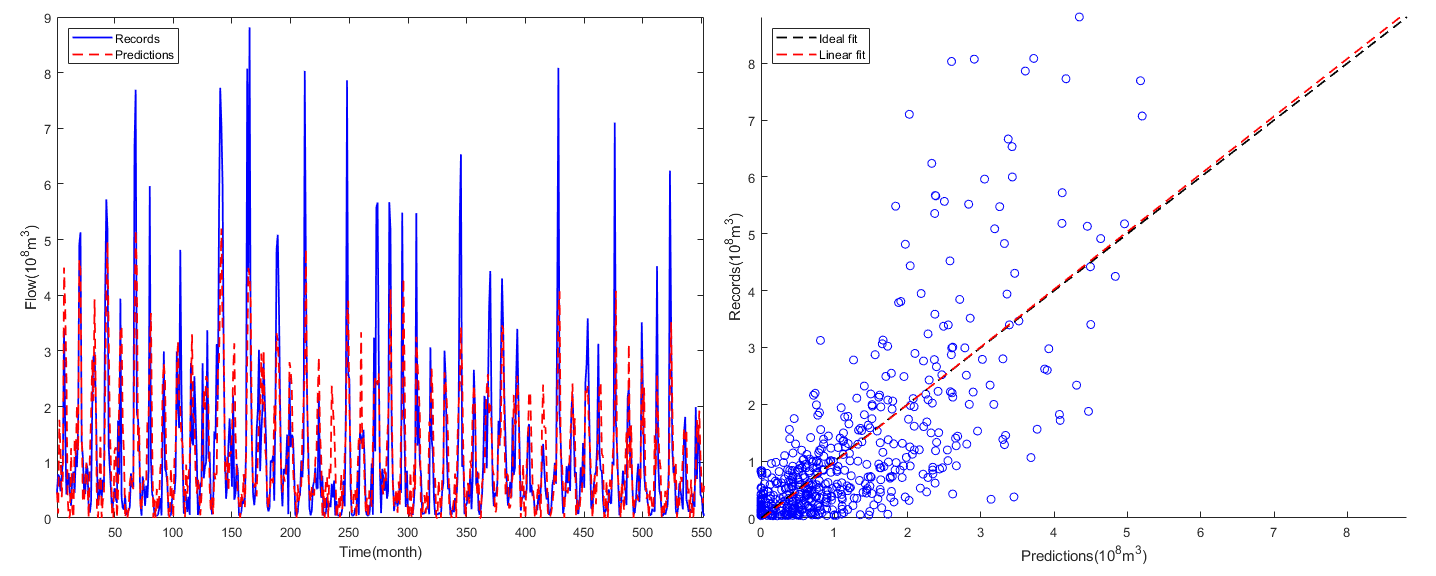

ha =     1.0006
    2.0006


x =          0    0.0890    0.1781    0.2671    0.3561    0.4452    0.5342    0.6232    0.7123    0.8013    0.8904    0.9794    1.0684    1.1575    1.2465    1.3355    1.4246    1.5136    1.6026    1.6917    1.7807    1.8697    1.9588    2.0478    2.1369    2.2259    2.3149    2.4040    2.4930    2.5820    2.6711    2.7601    2.8491    2.9382    3.0272    3.1162    3.2053    3.2943    3.3834    3.4724    3.5614    3.6505    3.7395    3.8285    3.9176    4.0066    4.0956    4.1847    4.2737    4.3627


c =     1.0140   -0.0317


y =    -0.0317    0.0586    0.1488    0.2391    0.3294    0.4197    0.5100    0.6003    0.6906    0.7808    0.8711    0.9614    1.0517    1.1420    1.2323    1.3225    1.4128    1.5031    1.5934    1.6837    1.7740    1.8643    1.9545    2.0448    2.1351    2.2254    2.3157    2.4060    2.4962    2.5865    2.6768    2.7671    2.8574    2.9477    3.0380    3.1282    3.2185    3.3088    3.3991    3.4894    3.5797    3.6699    3.7602    3.8505    3.9408    4.0311    4.1214    4.2117    4.3019    4.3922


y = 1.014*x + -0.031727


ans =     1.0140   -0.0317



metrics=[p_,q_,elapsedTime,nse_train,nrmse_train,ppts_train,nse_dev,nrmse_dev,ppts_dev,nse_test,nrmse_test,ppts_test];
metrics_table = array2table(metrics, 'VariableNames', {'p','q','time_cost','train_nse','train_nrmse','train_ppts','dev_nse','dev_nrmse','dev_ppts','test_nse','test_nrmse','test_ppts'});
writetable(metrics_table, strcat(save_path,'metrics.csv'));
train_results=[train,train_pred];
dev_results=[dev,dev_pred];
test_results=[test,test_pred];
train_table=array2table(train_results, 'VariableNames',{'train_y','train_pred'});
dev_table=array2table(dev_results, 'VariableNames',{'dev_y','dev_pred'});
test_table=array2table(test_results, 'VariableNames',{'test_y','test_pred'});
writetable(train_table, strcat(save_path,'train_pred.csv'));
writetable(dev_table, strcat(save_path,'dev_pred.csv'));
writetable(test_table, strcat(save_path,'test_pred.csv'));

plot_pred(train,train_pred,strcat(save_path,'train_pred.png'))

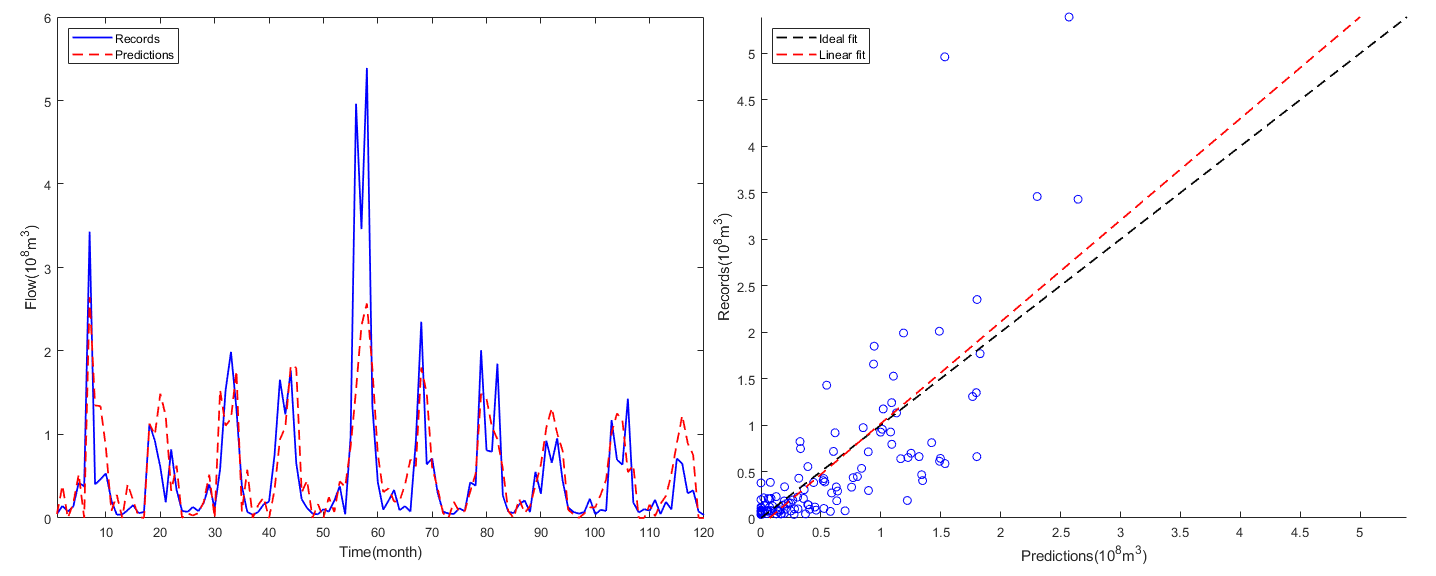

ha =     3.0006
    4.0006


x =          0    0.0544    0.1089    0.1633    0.2178    0.2722    0.3267    0.3811    0.4356    0.4900    0.5445    0.5989    0.6534    0.7078    0.7623    0.8167    0.8712    0.9256    0.9801    1.0345    1.0890    1.1434    1.1978    1.2523    1.3067    1.3612    1.4156    1.4701    1.5245    1.5790    1.6334    1.6879    1.7423    1.7968    1.8512    1.9057    1.9601    2.0146    2.0690    2.1235    2.1779    2.2324    2.2868    2.3413    2.3957    2.4501    2.5046    2.5590    2.6135    2.6679


c =     1.0938   -0.0773


y =    -0.0773   -0.0178    0.0418    0.1013    0.1609    0.2204    0.2800    0.3396    0.3991    0.4587    0.5182    0.5778    0.6373    0.6969    0.7565    0.8160    0.8756    0.9351    0.9947    1.0542    1.1138    1.1734    1.2329    1.2925    1.3520    1.4116    1.4711    1.5307    1.5903    1.6498    1.7094    1.7689    1.8285    1.8880    1.9476    2.0072    2.0667    2.1263    2.1858    2.2454    2.3049    2.3645    2.4241    2.4836    2.5432    2.6027    2.6623    2.7219    2.7814    2.8410


y = 1.0938*x + -0.077341


ans =     1.0938   -0.0773


plot_pred(dev,dev_pred,strcat(save_path,'dev_pred.png'))

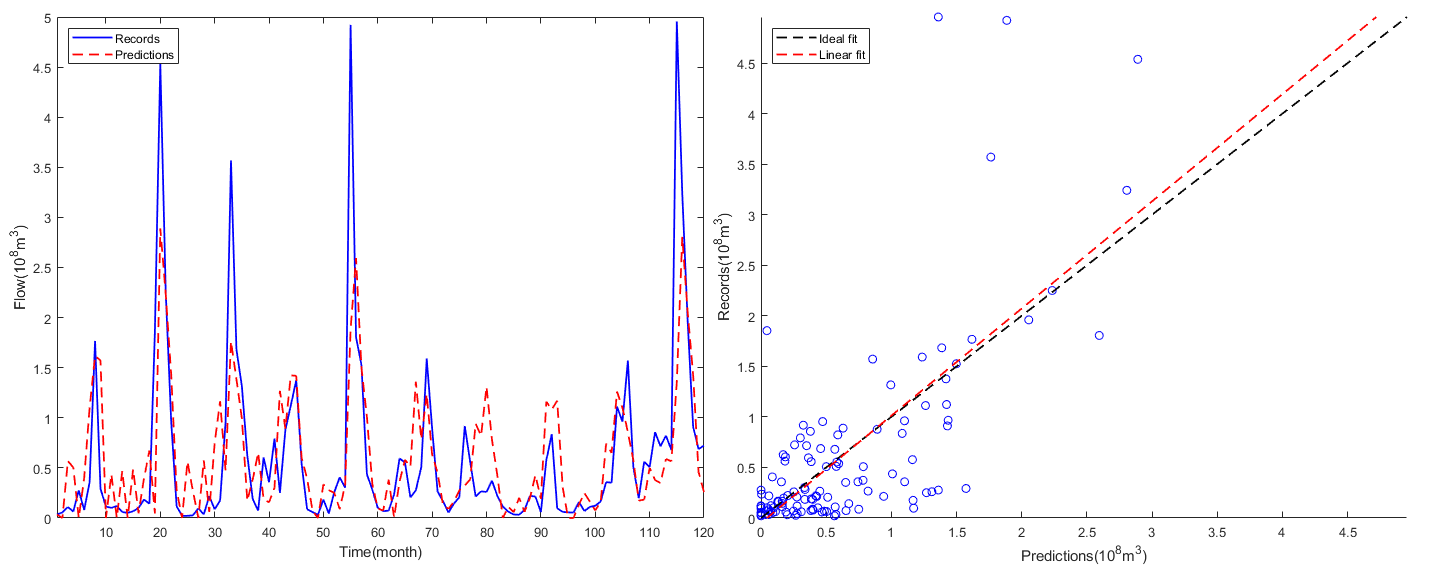

ha =     5.0006
    6.0006


x =          0    0.0501    0.1001    0.1502    0.2002    0.2503    0.3003    0.3504    0.4004    0.4505    0.5005    0.5506    0.6006    0.6507    0.7007    0.7508    0.8008    0.8509    0.9009    0.9510    1.0010    1.0511    1.1011    1.1512    1.2012    1.2513    1.3013    1.3514    1.4014    1.4515    1.5015    1.5516    1.6016    1.6517    1.7017    1.7518    1.8018    1.8519    1.9019    1.9520    2.0020    2.0521    2.1021    2.1522    2.2022    2.2523    2.3023    2.3524    2.4024    2.4525


c =     1.0600   -0.0476


y =    -0.0476    0.0054    0.0585    0.1115    0.1646    0.2176    0.2707    0.3237    0.3768    0.4299    0.4829    0.5360    0.5890    0.6421    0.6951    0.7482    0.8012    0.8543    0.9074    0.9604    1.0135    1.0665    1.1196    1.1726    1.2257    1.2787    1.3318    1.3848    1.4379    1.4910    1.5440    1.5971    1.6501    1.7032    1.7562    1.8093    1.8623    1.9154    1.9685    2.0215    2.0746    2.1276    2.1807    2.2337    2.2868    2.3398    2.3929    2.4459    2.4990    2.5521


y = 1.06*x + -0.047642


ans =     1.0600   -0.0476


plot_pred(test,test_pred,strcat(save_path,'test_pred.png'))